# Bitacora simulaciones del enfoque del espacio de estados

# Planta de primer orden

La planta de primer orden se trata de de la planta de nivel de agura:

clc;clear;close all
Tau = 265;
J = 0.923;
num=[J];
den=[Tau 1];
G=tf(num,den)


G =
 
    0.923
  ---------
  265 s + 1
 
Continuous-time transfer function.



En el espacio de estados

A = -1/Tau;
B = J/Tau;
C = 1;
D = 0;

En todos los casos se elegira un perido de mustreo en base al criterio del ancho de banda:


$$\omega_s =N_m \;\omega_m \;\;\;\;\;\;\;\;\;\;\;20\le N_m \le 50$$


Se va a elegir el valro medio para $N_m$:

Nm = 50

Nm = 50

$\omega {\;}_m$:

wm = bandwidth(feedback(G,1))

wm = 0.0072

ws = Nm * wm

ws = 0.3620

fs = ws/(2*pi)

fs = 0.0576

Ts = 1/fs

Ts = 17.3583

Redondeando:

Ts = 5

Ts = 5

## Definicion de valores maximos y minimos

La definicion del valor horizontal maximo y minimo del unico polo. El polo a lazo abierto es:

eig(A)

ans = -0.0038

Por lo que se propone emepzar desde -0.001 e ir aumentando con pasos de 0.0005 hasta -0.01.

paso_horizontal = 0.0005;
pol=-0.001:-paso_horizontal:-0.01;

Para el umbral, empezaremos con valor muy pequeño como 0.001, hasta un valor de 1. Si estos valores resultan pobres se aumentara el rango luego.

um = .001:.01:0.2;

## Simulaciones

Ya se tienen definidos los maximos y minimos, en este caso es posible realizar las simulaciones sistematizadas 

clear y x t Kd u e N M eventos norma
disp('Start')

Start


t=0:10:10000;
incertidumbre_de_A = A;
incertidumbre_de_B = B;
[yy,xx,t,Kdd,uu,ee,Nn,Mm,eventoss,normas]=state_approach_based(A,B,C,-0.,t,um(1),incertidumbre_de_A,incertidumbre_de_B,Ts,-1,0);

% for pol_hor=1:length(pol)
%     for um_val=1:length(um)
%         [y(um_val,:,pol_hor),x(um_val,:,pol_hor),t,Kd,u(um_val,:,pol_hor),e(um_val,:,pol_hor),N(um_val,pol_hor),M(um_val,pol_hor),eventos(um_val,:,pol_hor),norma(um_val,:,pol_hor)]=state_approach_based(A,B,C,pol(pol_hor),t,um(um_val),incertidumbre_de_A,incertidumbre_de_B,Ts,-1,0);
%         [error_est(um_val,pol_hor),t_asent(um_val,pol_hor),sobre_pico_porcentaje(um_val,pol_hor)] = datos_exp(y(um_val,:,pol_hor),0,t,2);
%     end
% end
% disp('End')

End


## Graficacion de algunos resultados

%load('Datos_p_primer_orden_ss.mat')

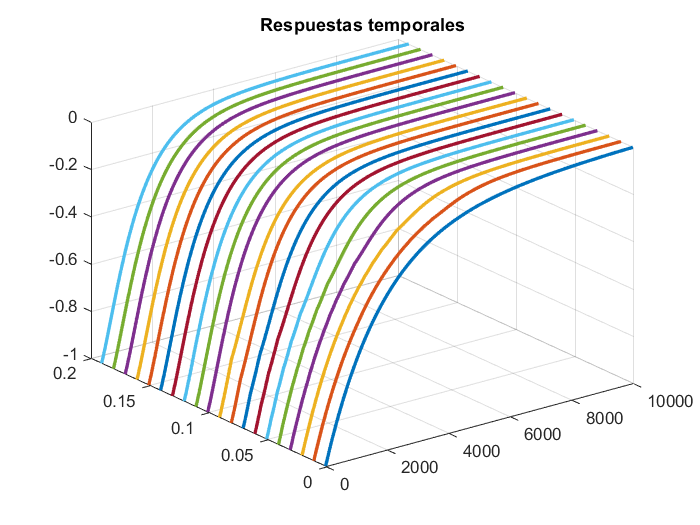


nro_pol=1;
plot3(t,ones(1,length(t))*um(1),y(1,:,nro_pol),'LineWidth',2)
grid on
title('Respuestas temporales')
hold on
for um_val=2:length(um)
    plot3(t,ones(1,length(t))*um(um_val),y(um_val,:,nro_pol),'LineWidth',2)
end
hold off

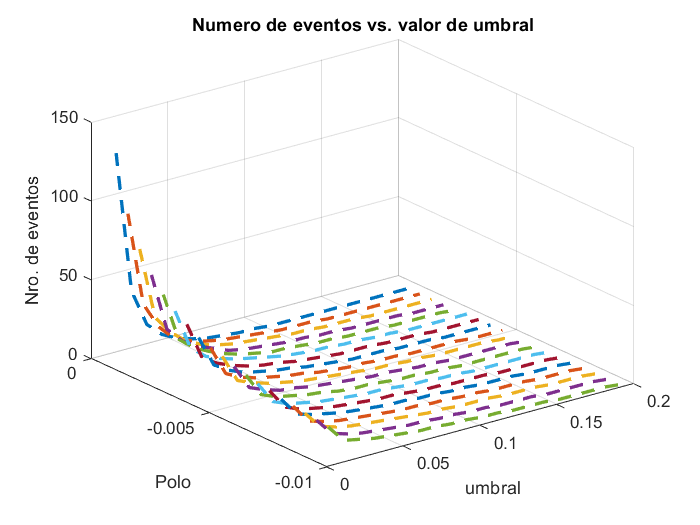

nro_pol=1;
plot3(um,ones(1,length(um))*pol(1),N(:,1),'--','LineWidth',2)
grid on
title('Numero de eventos vs. valor de umbral')
hold on
for pol_hor=2:length(pol)
    plot3(um,ones(1,length(um))*pol(pol_hor),N(:,pol_hor),'--','LineWidth',2)
end
hold off
xlabel('umbral')
ylabel('Polo')
zlabel('Nro. de eventos')

%save('Datos_p_primer_orden_ss','A','B','C','um','pol','incertidumbre_de_A','incertidumbre_de_B','y','x','t','Ts','Kd','u','e','N','M','eventos','norma','error_est','t_asent','sobre_pico_porcentaje')
save('Datos_p_primer_orden_ss_V2','A','B','C','um','pol','incertidumbre_de_A','incertidumbre_de_B','y','x','t','Ts','Kd','u','e','N','M','eventos','norma','error_est','t_asent','sobre_pico_porcentaje')

# Planta de segundo orden

La plante de segundo orden se trata de la planta del motor de la unidad de seleccion. En este caso podemos usar esa misma planta como plana te de segundo y tercer orden. En el caso de segundo orden se trata de un control de velocidad.

clc;clear;close all
num = 48.8;
den = [1 5.163 15.58];

A = [0 1;-15.58 -5.163]
B = [0;48.8]
C = [1 0]

En todos los casos se elegira un perido de mustreo en base al criterio del ancho de banda:


$$\omega_s =N_m \;\omega_m \;\;\;\;\;\;\;\;\;\;\;20\le N_m \le 50$$


Se va a elegir el valro medio para $N_m$:

Nm = 35

$\omega {\;}_m$:

wm = bandwidth(feedback(tf(num,den),1))
ws = Nm * wm
fs = ws/(2*pi)
Ts = 1/fs

Redondeando:

Ts = 15e-3

## Definicion de valores maximos y minimos

La definicion del valor horizontal maximo y minimo para los polos, horizontal y verticalmente hablando. Los polos a lazo abierto son:

eig(A)

Dadas las limitaciones fisicas reales de esta planta, estos polos muestran la velocidad maxima del sistema. Por lo que se propone que la posicion horizontal de los polos a lazo abierto sean el maximo horizontal.

Por lo que se propone emepzar desde -1 e ir aumentando con pasos de 0.5 hasta -2.5.

paso_horizontal = 0.5;
pol_horizontal=-1:-paso_horizontal:-2.5;

Para el polo vertical podemos tener un paso un poco mas grande con el fin de tener un abanico mas amplio de valores.

paso_vertical = 1;
pol_vertical = 1:paso_vertical:4

Para el umbral, empezaremos con valor muy pequeño como 0.001, hasta un valor de 1. Si estos valores resultan pobres se aumentara el rango luego.

um = .001:.5:10;

## Simulaciones

Ya se tienen definidos los maximos y minimos, en este caso es posible realizar las simulaciones sistematizadas 

clear y x t Kd u e N M eventos norma
disp('Start')
t=0:5e-3:6;
incertidumbre_de_A = A;
incertidumbre_de_B = B;
pol = [pol_horizontal(1)+j*pol_vertical(1) pol_horizontal(1)-j*pol_vertical(1)]
%[yy,xx(:,:,2),t,Kdd,uu,ee,Nn,Mm,eventoss,normas]=state_approach_based(A,B,C,[pol(1) pol(2)],t,um(1),incertidumbre_de_A,incertidumbre_de_B,Ts,[-1;0],[0;0]);

for pol_vert = 1:length(pol_vertical)
    for pol_hor=1:length(pol_horizontal)
        pol = [pol_horizontal(pol_hor)+j*pol_vertical(pol_vert) pol_horizontal(pol_hor)-j*pol_vertical(pol_vert)];
        for um_val=1:length(um)
            [y(um_val,:,pol_hor,pol_vert),x(:,:,um_val,pol_hor,pol_vert),t,Kd,u(um_val,:,pol_hor,pol_vert),e(um_val,:,pol_hor,pol_vert),N(um_val,pol_hor,pol_vert),M(um_val,pol_hor,pol_vert),eventos(um_val,:,pol_hor,pol_vert),norma(um_val,:,pol_hor,pol_vert)]=state_approach_based(A,B,C,[pol(1) pol(2)],t,um(um_val),incertidumbre_de_A,incertidumbre_de_B,Ts,[-1;0],[0;0]);
            [error_est(um_val,pol_hor,pol_vert),t_asent(um_val,pol_hor,pol_vert),sobre_pico_porcentaje(um_val,pol_hor,pol_vert)] = datos_exp(y(um_val,:,pol_hor,pol_vert),0,t,2);
        end
    end
end
disp('End')

save('Datos_p_segundo_orden_ss','A','B','C','um','pol','incertidumbre_de_A','incertidumbre_de_B','y','x','t','Ts','Kd','u','e','N','M','eventos','norma','error_est','t_asent','sobre_pico_porcentaje')

# Planta de tercer orden

La plante de segundo orden se trata de la planta del motor de la unidad de seleccion. En este caso podemos usar esa misma planta como plana te de segundo y tercer orden. En el caso de segundo orden se trata de un control de velocidad.

clc;clear;close all
num = 48.8;
den = [1 5.163 15.58 0]

den =     1.0000    5.1630   15.5800         0



A = [0 1 0;0 0 1;0 -15.58 -5.163]

A =          0    1.0000         0
         0         0    1.0000
         0  -15.5800   -5.1630


B = [0;0;48.8]

B =          0
         0
   48.8000


C = [1 0 0]

C =      1     0     0


En todos los casos se elegira un perido de mustreo en base al criterio del ancho de banda:


$$\omega_s =N_m \;\omega_m \;\;\;\;\;\;\;\;\;\;\;20\le N_m \le 50$$


Se va a elegir el valro medio para $N_m$:

Nm = 35

Nm = 35

$\omega {\;}_m$:

wm = bandwidth(feedback(tf(num,den),1))

wm = 4.6515

ws = Nm * wm

ws = 162.8042

fs = ws/(2*pi)

fs = 25.9111

Ts = 1/fs

Ts = 0.0386

Redondeando:

Ts = 40e-3

Ts = 0.0400

## Definicion de valores maximos y minimos

La definicion del valor horizontal maximo y minimo para los polos, horizontal y verticalmente hablando. Los polos a lazo abierto son:

eig(A)

ans =    0.0000 + 0.0000i
  -2.5815 + 2.9859i
  -2.5815 - 2.9859i


Dadas las limitaciones fisicas reales de esta planta, estos polos muestran la velocidad maxima del sistema. Por lo que se propone que la posicion horizontal de los polos a lazo abierto sean el maximo horizontal.

Por lo que se propone emepzar desde -1 e ir aumentando con pasos de 0.5 hasta -2.5.

paso_horizontal = 0.5;
pol_horizontal=-1:-paso_horizontal:-2.5;

Para el polo vertical podemos tener un paso un poco mas grande con el fin de tener un abanico mas amplio de valores.

paso_vertical = 1;
pol_vertical = 1:paso_vertical:4;

Para el tecer polo se toma en cuenta que es un integrador, por lo que hay que moverlo, se elegiran 3 valores, desde -1 hasta -15:

paso_tercer_polo = 7;
pol_tercer = -1:-paso_tercer_polo:-15;

Para el umbral, empezaremos con valor muy pequeño como 0.001, hasta un valor de 1. Si estos valores resultan pobres se aumentara el rango luego.

um = .001:.5:10;

## Simulaciones

Ya se tienen definidos los maximos y minimos, en este caso es posible realizar las simulaciones sistematizadas 

clear y x t Kd u e N M eventos norma
disp('Start')

Start


t=0:20e-3:18;
incertidumbre_de_A = A;
incertidumbre_de_B = B;
%pol = [pol_tercer(1) pol_horizontal(1)+j*pol_vertical(1) pol_horizontal(1)-j*pol_vertical(1)];
%[yy,xx,t,Kdd,uu,ee,Nn,Mm,eventoss,normas]=state_approach_based(A,B,C,[pol(1) pol(2) pol(3)],t,um(1),incertidumbre_de_A,incertidumbre_de_B,Ts,[-1;0;0],[0;0;0]);

for tercer_pol = 1:length(pol_tercer)
    for pol_vert = 1:length(pol_vertical)
        for pol_hor=1:length(pol_horizontal)
            
            pol = [pol_tercer(tercer_pol) pol_horizontal(pol_hor)+j*pol_vertical(pol_vert) pol_horizontal(pol_hor)-j*pol_vertical(pol_vert)];
            for um_val=1:length(um)
                [y(um_val,:,pol_hor,pol_vert,tercer_pol),x(:,:,um_val,pol_hor,pol_vert,tercer_pol),t,Kd,u(um_val,:,pol_hor,pol_vert,tercer_pol),e(um_val,:,pol_hor,pol_vert,tercer_pol),N(um_val,pol_hor,pol_vert,tercer_pol),M(um_val,pol_hor,pol_vert,tercer_pol),eventos(um_val,:,pol_hor,pol_vert,tercer_pol),norma(um_val,:,pol_hor,pol_vert,tercer_pol)]=state_approach_based(A,B,C,[pol(1) pol(2) pol(3)],t,um(um_val),incertidumbre_de_A,incertidumbre_de_B,Ts,[-1;0;0],[0;0;0]);
                [error_est(um_val,pol_hor,pol_vert,tercer_pol),t_asent(um_val,pol_hor,pol_vert,tercer_pol),sobre_pico_porcentaje(um_val,pol_hor,pol_vert,tercer_pol)] = datos_exp(y(um_val,:,pol_hor,pol_vert,tercer_pol),0,t,2);
            end
        end
    end
end
disp('End')

save('Datos_p_terer_orden_ss','A','B','C','um','pol','incertidumbre_de_A','incertidumbre_de_B','y','x','t','Ts','Kd','u','e','N','M','eventos','norma','error_est','t_asent','sobre_pico_porcentaje')